# ***HSV***

***Obriu una imatge i comprovar que és una imatge RGB, fent servir la instrucció size. Mostrar la imatge per pantalla: imshow.***

I = imread('flor-de-loto.jpg');
%I = imresize(I,0.2);
[x y colors] = size(I)

x = 450

y = 735

colors = 3

%%% si colors == 3, llavors la imatge es rgb
imshow(I);

***Obtenir del usuari el rectangle que emmarca l’objecte (fig. 4) que vol segmentar. Utilitzeu rect = getrect. Vigileu que la variable rect té el format (x, y, w, h); posició, amplada alçada (en lloc de fila i columna).***

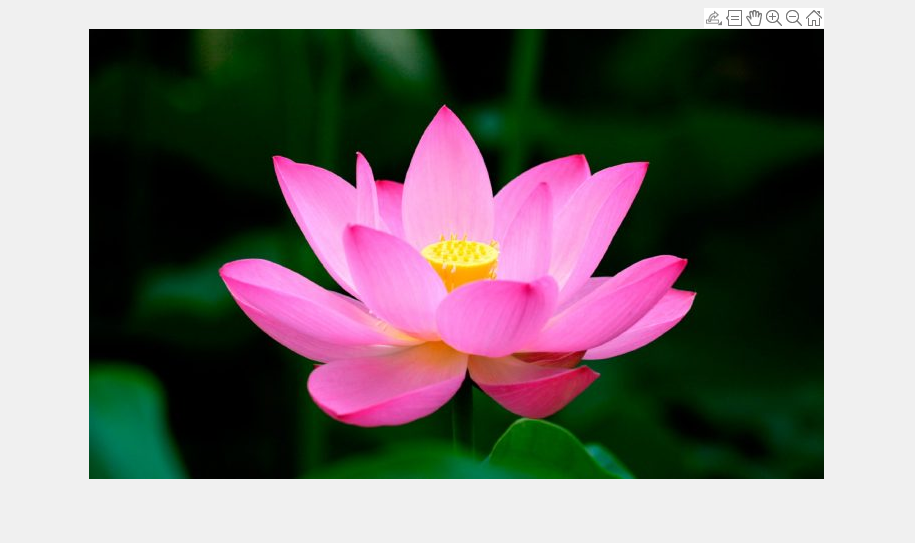

rec = round(getrect);

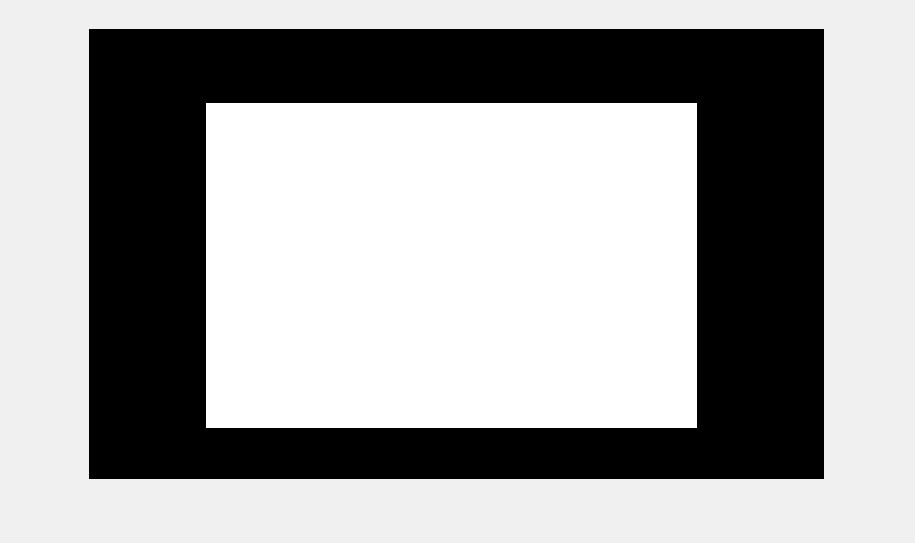

ymin = rec(1);
xmin = rec(2);
height = rec(3);
width = rec(4);
mask = zeros(x,y);
mask(xmin:(xmin+width),ymin:(ymin+height)) = 1;


imshow(mask,[]);

***Obtenir la imatge HSV: rgb2hsv. Posteriorment, caldrà provar també en altres espai de color com RGB o CIE Lab.***

***Preparem la taula pel kmeans. Cal construir una taula O amb tantes files com píxels i les següents columnes:***

***[Hx Hy S V]***

***On Hx Hy són les coordenades circulars 2D del hue. Recordeu que les funcions sin i cos treballen en radiants i el hue està especificat entre 0 i 1.***

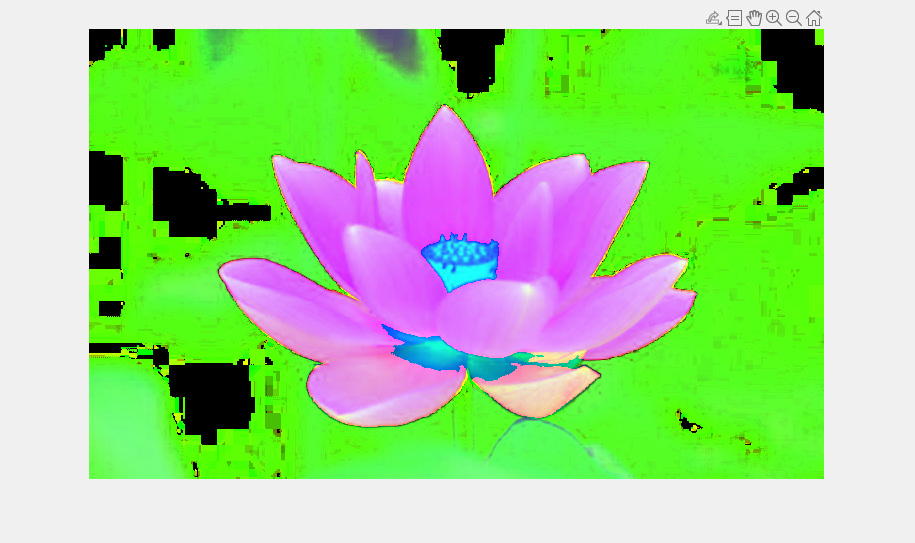

%rec = getrect();
HSV = rgb2hsv(I);
imshow(HSV,[]);


%R = I(:,:,1);
%G = I(:,:,2);
%B = I(:,:,3);
%O = double([R(:),G(:),B(:)]);

%% Cal construir una taula O amb tantes files com píxels i les següents columnes:
Hx = cos(HSV(:,:,1)*180/pi); Hx =reshape(Hx,[],1);
Hy = sin(HSV(:,:,1)*180/pi); Hy =reshape(Hy,[],1);
S = HSV(:,:,2); S =reshape(S,[],1);
V = HSV(:,:,3); V =reshape(V,[],1);
O = double([Hx Hy S V]);

***Agrupem els colors en k classes amb kmeans i obtenim la classificació C, per exemple  ***

***k = 15;  ***

***C = kmeans(O,k);***

***El valor més adequat del paràmetre k dependrà de la complexitat de la imatge, però normalmente es mou entre 10 a 20 colors.  ***

k = 15

k = 15

[L, centroids] = kmeans(O,k)

L =      6
     6
     6
     6
     6
     6
     6
     6
     6
     6


centroids =     0.9709    0.2314    0.9927    0.1179
   -0.9666   -0.1456    0.9365    0.1041
   -0.5158    0.8292    0.9536    0.1269
    0.9455    0.2753    0.4905    0.9685
    0.3903    0.9022    0.9742    0.1199
    0.9996    0.0004    0.0028    0.0031
   -0.8543    0.4035    0.6121    0.8167
    0.9376   -0.2955    0.4457    0.9811
   -0.6005   -0.7387    0.7612    0.5935
    0.5818    0.7913    0.5360    0.9458


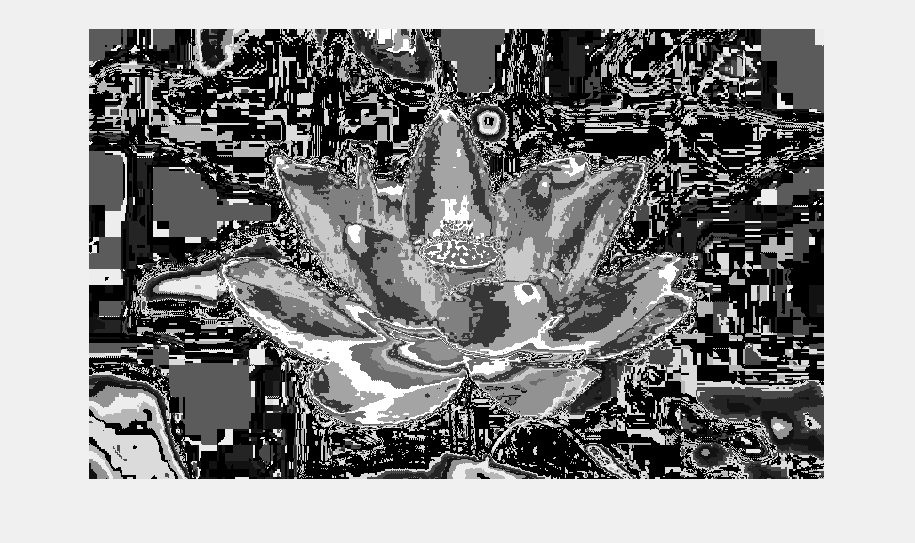

%plot(L(:,1),'.')
[f,c,p] = size(HSV);
S = reshape(L,[f,c]);
imshow(S,[])

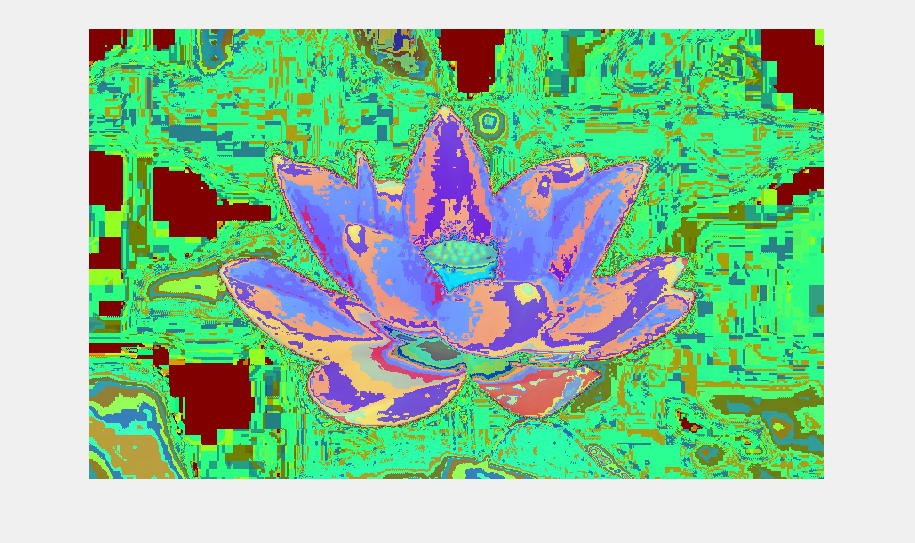

Li = labeloverlay(HSV,S);
imshow(Li,[])

***Amb els colors dels representants de cada classe obtinguda amb la funció kmeans mostreu la imatge resultant de quantificar els colors de la imatge a k representants . Vegeu la documentació d’ajuda de la funció kmeans:***

***[idx, Rep] = kmeans(O,k) ***

***% returns the k cluster centroid locations in the k-by-p matrix Rep.***

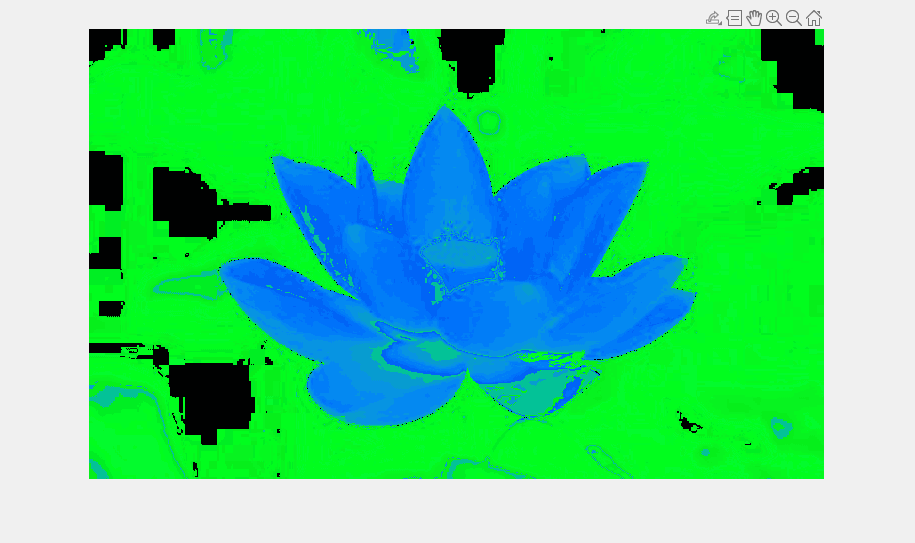

Hi = zeros(x,y);
Si = zeros(x,y);
Vi = zeros(x,y);
for i = 1:x
    for j = 1:y
        Hi(i,j) = (acos(centroids(S(i,j),1)) * pi/180 + asin(centroids(S(i,j),2)) * pi/180)/2;
        Si(i,j) = centroids(S(i,j),3);
        Vi(i,j) = centroids(S(i,j),4);
    end
end
IMG = cat(3, Hi, Si, Vi);
imshow(IMG)

%%creiem que la iimatge resultant es de color blau perque el centre de la
%%flor ho es, i per tant el centroide del rosa cau dins del blau.

***Ara la idea central d’aquesta pràctica és veure quins colors cauen a dins del rectangle i quins fora. Per tal fi, construïm una imatge de valors booleans anomenada MASK de la mateixa mida que la imatge inicial amb els valors a zero si està fora del rectangle i 1 si està dins (fig 5). Nota: és molt fàcil construir-la amb una sola sentència, no us compliqueu a fer funcions de si un píxel està dins o fora d’un rectangle...***

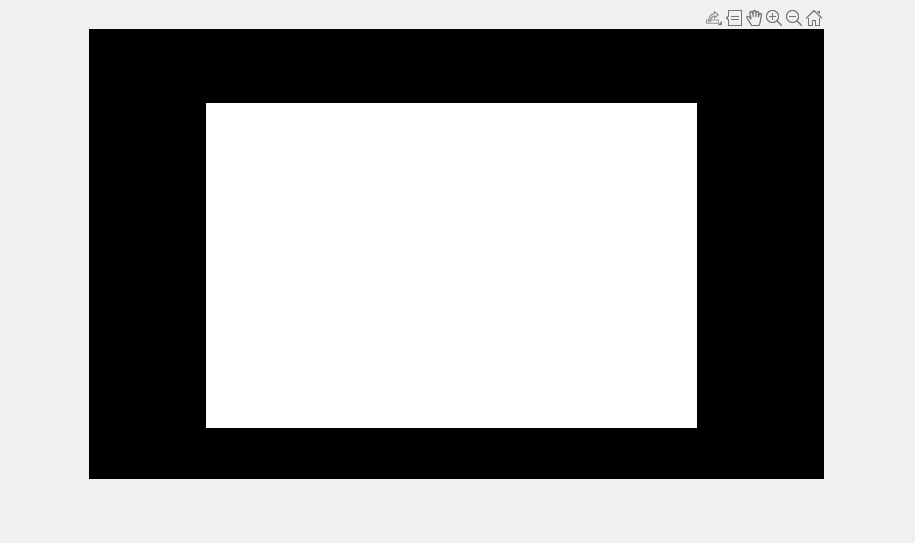

imshow(mask)

***Ara construïm un vector H que indicarà si un color cau dins del rectangle o no. Tal que H = [C, MASK(:)]; Observeu que H és una taula que indica si tal color C és dins o fora de la mascara.***

H = [L,mask(:)]

H =      6     0
     6     0
     6     0
     6     0
     6     0
     6     0
     6     0
     6     0
     6     0
     6     0


***A continuació, comptem per a cada color de C quants píxels han caigut a fora i quants a dins. Guardem els resultats en dos arrays Hist0 i Hist1. Evidentment, la mida de Hist0 i Hist1 ha de ser igual al nombre de classes k. ***

Hist0 = hist(H(H(:,2)==0),[1:k]); %Obtenim els punts de fora 
Hist1 = hist(H(H(:,2)==1),[1:k]); %Obtenim els punts de dins

***Llavors decidim si un representant de color pertany a la figura que es vol segmentar comparant les seves aparicions dins i fora del rectangle. Guardem la decisió en un vector anomenat RES. Quelcom com RES = Hist1 > Hist0;***

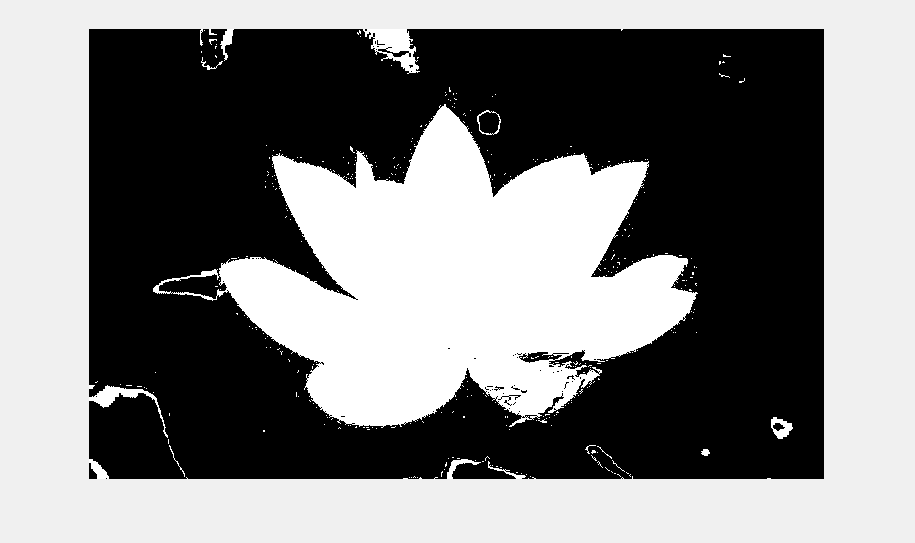

RES = Hist1 > Hist0;
M = RES(H(:,1)); %Tots els elements de H que tenen una k a 1
MFINAL = reshape(M,size(I,1),size(I,2));
imshow(MFINAL);

***Casi per últim, decidim per a cada  píxel de la matriu H si forma part de la figura o no utilitzant la informació que conté el vector RES. Guardem el resultat en un vector M i el mostrem per pantalla ***

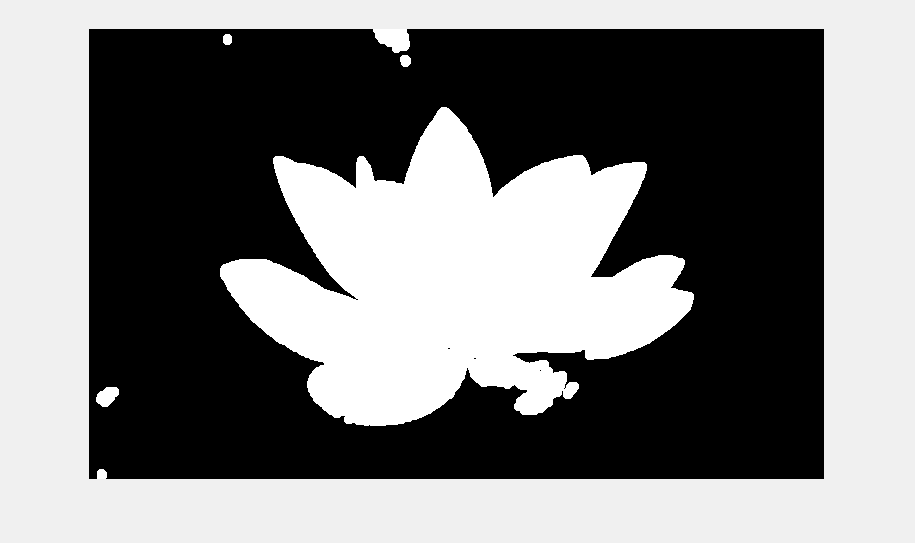

se = strel('disk',5);
MFINAL2 = imopen(MFINAL,se);
%MFINAL2 = medfilt2(MFINAL2,[10,10]);
imshow(MFINAL2);

***I per últim mostrem l’objecte segmentat de mida més gran.***

C = bwconncomp(MFINAL2)

C = struct with fields:
    Connectivity: 8
       ImageSize: [450 735]
      NumObjects: 6
    PixelIdxList: {[322×1 double]  [90×1 double]  [85622×1 double]  [87×1 double]  [642×1 double]  [109×1 double]}


npixels = cellfun(@numel,C.PixelIdxList);
[m,i] = max(npixels)

m = 85622

i = 3

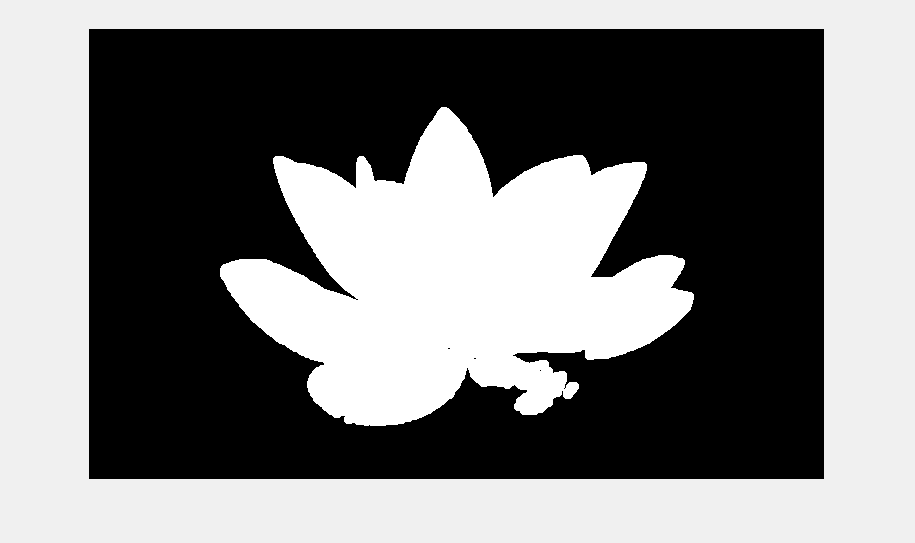


%%borrem totes le taques menys la més gran
[f c] = size(MFINAL2);
F = zeros(f,c);
F(C.PixelIdxList{i})=1;
imshow(F)

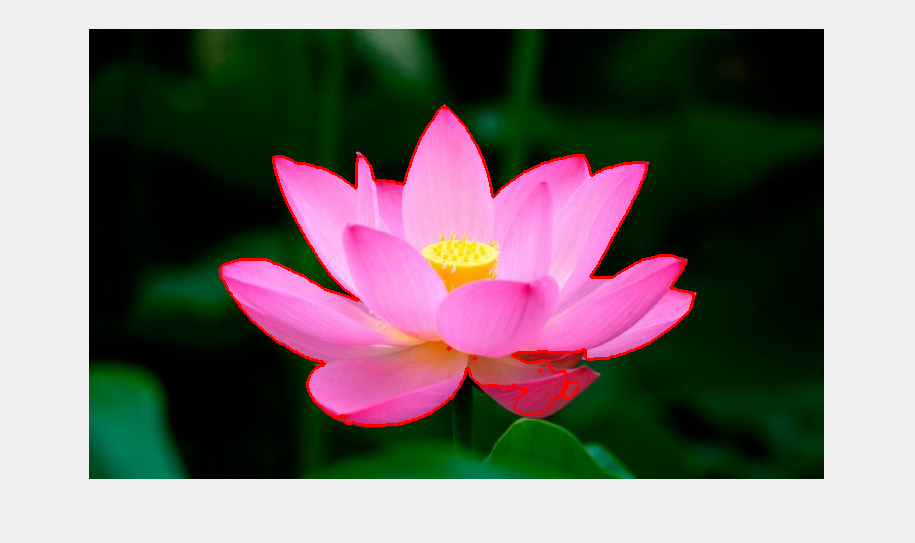


border = bwmorph(F,'remove');
se = strel('disk',1);
border = imdilate(border,se);

R = I(:,:,1); R(border == 1) = 255;
G = I(:,:,2); G(border == 1) = 0;
B = I(:,:,3); B(border == 1) = 0;

cercle = cat(3, R,G,B);
imshow(cercle)

# ***RGB***

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = double([R(:),G(:),B(:)]);

[L, centroids] = kmeans(O,k);
centroids = round(centroids)

centroids =      1    25     1
   252   133   219
   247   100   195
   112    37    47
     1   117    75
     1     5     1
   179    52    82
   251   224   101
   233   138    36
   222    89   154


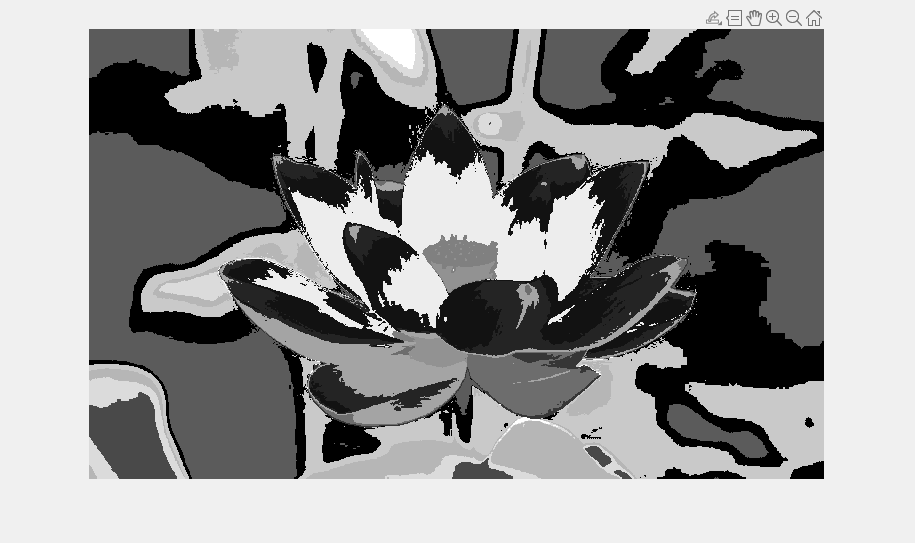

%plot(L(:,1),'.')
[f,c,p] = size(I);
S = reshape(L,[f,c]);
imshow(S,[])

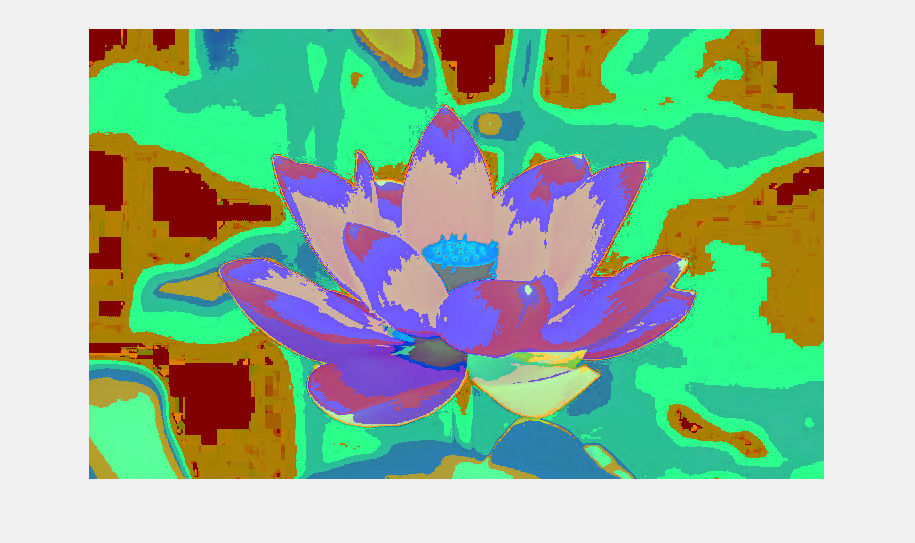

Li = labeloverlay(HSV,S);
imshow(Li,[])

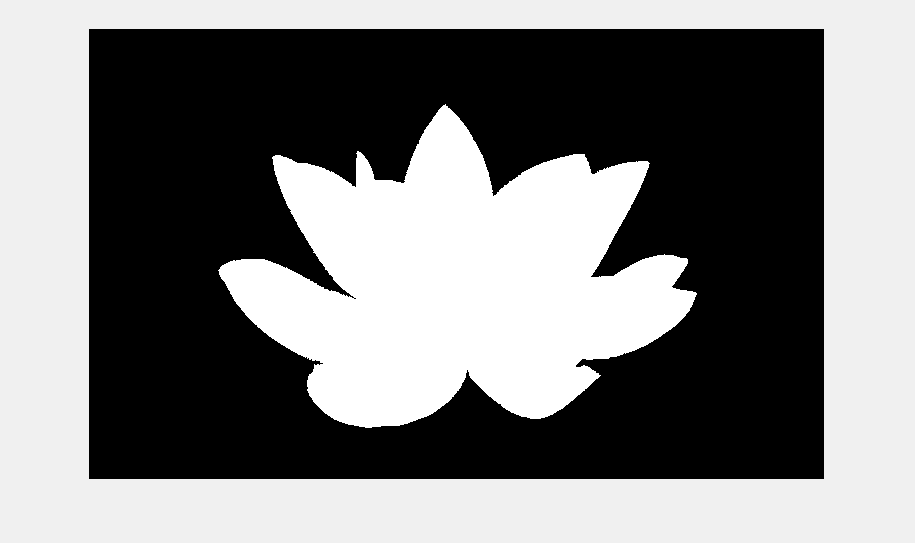


H = [L,mask(:)];
Hist0 = hist(H(H(:,2)==0),[1:k]); %Obtenim els punts de fora 
Hist1 = hist(H(H(:,2)==1),[1:k]); %Obtenim els punts de dins

RES = Hist1 > Hist0;
M = RES(H(:,1)); %Tots els elements de H que tenen una k a 1
MFINAL = reshape(M,size(I,1),size(I,2));
imshow(MFINAL);


se = strel('disk',5);
MFINAL2 = imopen(MFINAL,se);
%MFINAL2 = medfilt2(MFINAL2,[10,10]);
%%imshow(MFINAL2); en aquest cas no hi ha taques que eliminar

C = bwconncomp(MFINAL2)

C = struct with fields:
    Connectivity: 8
       ImageSize: [450 735]
      NumObjects: 1
    PixelIdxList: {[88673×1 double]}


npixels = cellfun(@numel,C.PixelIdxList);
[m,i] = max(npixels)

m = 88673

i = 1

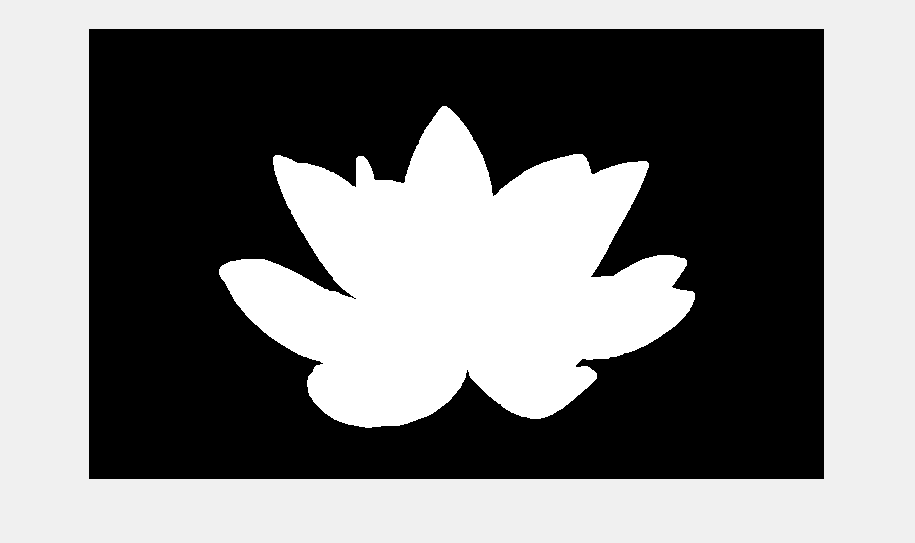


[f c] = size(MFINAL2);
F = zeros(f,c);
F(C.PixelIdxList{i})=1;
imshow(F)

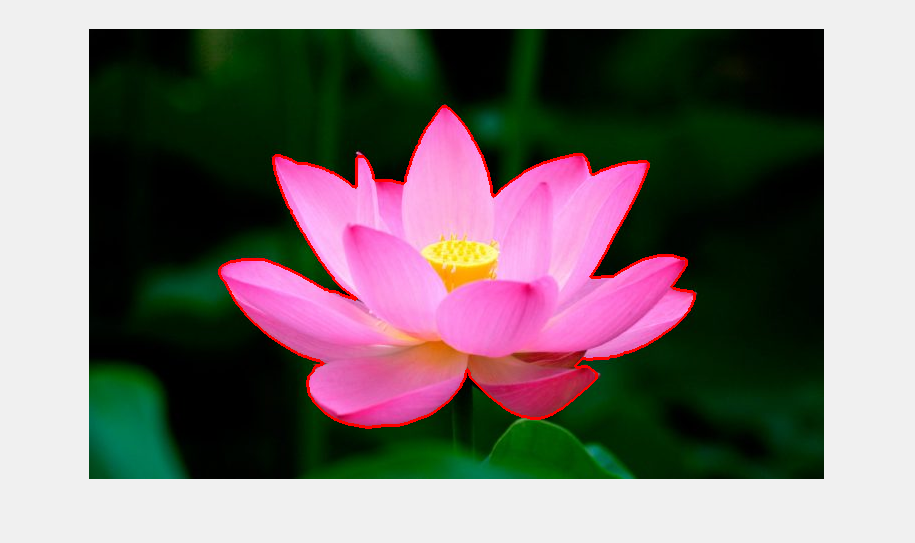


border = bwmorph(F,'remove');
se = strel('disk',1);
border = imdilate(border,se);

R = I(:,:,1); R(border == 1) = 255;
G = I(:,:,2); G(border == 1) = 0;
B = I(:,:,3); B(border == 1) = 0;

cercle = cat(3, R,G,B);
imshow(cercle)

**Com podem veure, en el nostre cas tractant la imatge en RGB obtenim una selecció més precísa que en HSV, ja que detecta millor el petal inferior que es de un color lleugerament més fosc**

# K-means Alternatiu

En aquest apartat procedirem a afegir altres fonts d'informació de píxel a les observacions del kmeans.

Per tant, ara provarem d'afegir la posició de cada píxel per efectuar l'algorisme.

Repetirem el mateix procediment anterior i modificarem la part del kmeans.

HSV = rgb2hsv(I);

Hx = cos(HSV(:,:,1)*180/pi); Hx =reshape(Hx,[],1);
Hy = sin(HSV(:,:,1)*180/pi); Hy =reshape(Hy,[],1);
S = HSV(:,:,2); S =reshape(S,[],1);
V = HSV(:,:,3); V =reshape(V,[],1);

w = size(I,2);
h = size(I,1);
%obtenim les posicions dels píxels
xc = (1:w);
xc = ones(h,1)*xc/w; xc = reshape(xc,[],1);
yc = (1:h);
yc = yc'*ones(1,w)/h; yc = reshape(yc,[],1);

O = double([Hx Hy S V xc yc]);

%Realitzem el kmeans
k = 25;
% NOU KMEANS %
C = kmeans(O,k);

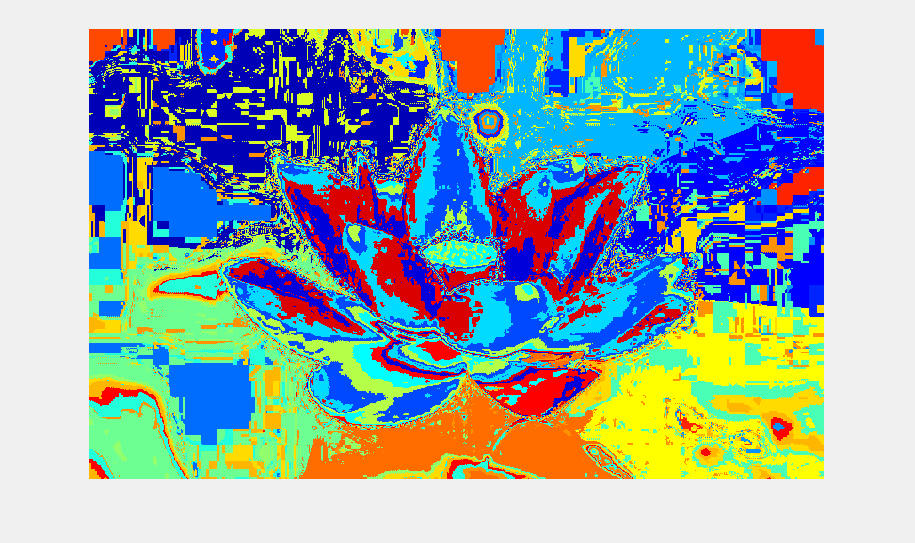

IC = reshape(C,[size(I,1)],[size(I,2)]);
rgb = label2rgb(IC);

Mask = zeros(size(I,1),size(I,2));
Mask(rec(2):(rec(2)+rec(4)),rec(1):(rec(1)+rec(3))) = 1;

H = [C, Mask(:)];
Hist0 = hist(H(H(:,2)==0),[1:k]); % H(:,2) == 0 retorna els valors fora del rectangle
                                    % H(H(:,2)==0) retorna els valors C de fora del rectangle
Hist1 = hist(H(H(:,2)==1),[1:k]); % El mateix pels punts de dins
RES = Hist1 > Hist0;
M = RES(H(:,1)); %Elements d'H que cauen tenen una k a 1 a RES
MFin = reshape(M,size(I,1),size(I,2));
imshow(rgb);

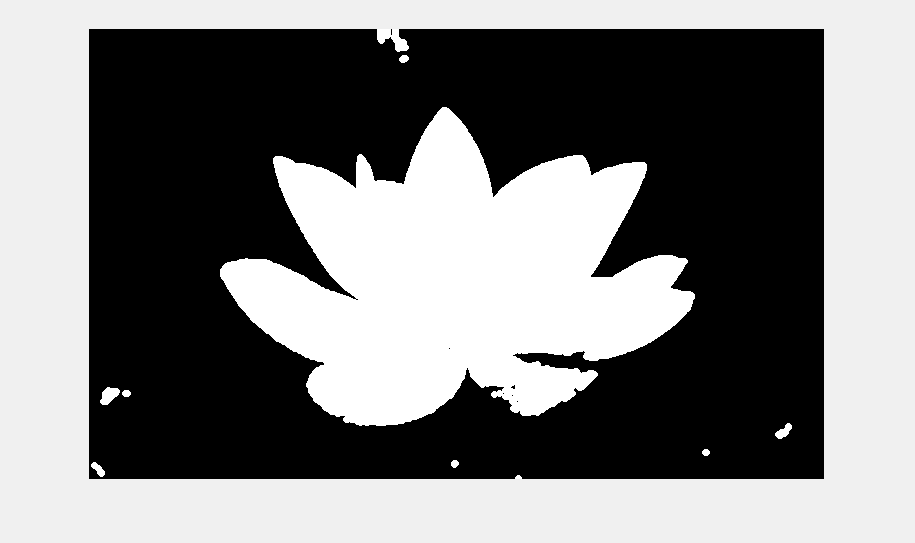

se = strel('disk',4);
MClean = imopen(MFin,se);
imshow(MClean)

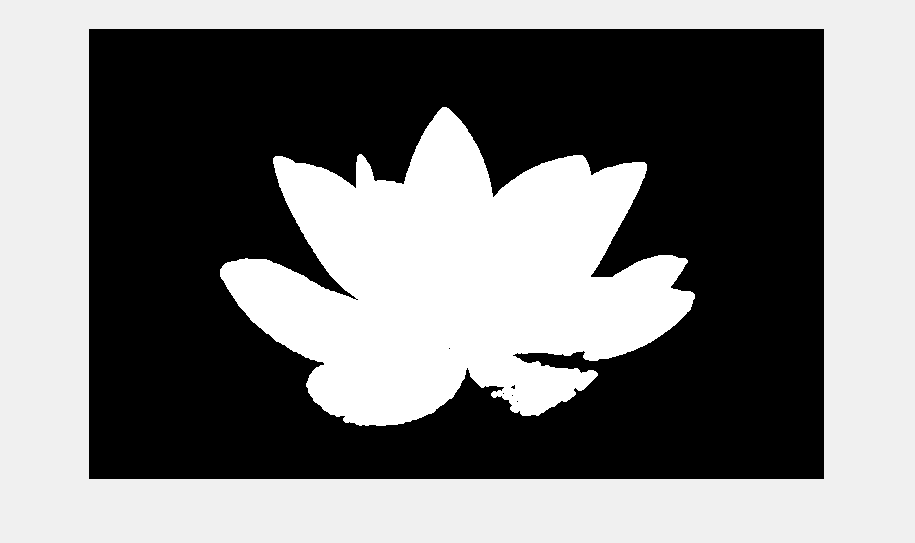

C2 = bwconncomp(MClean);
npixels = cellfun(@numel,C2.PixelIdxList);
[m,i] = max(npixels);
[f c] = size(MClean);
F = zeros(f,c);
F(C2.PixelIdxList{i})=1;
imshow(F);

Com podem veure en aquesta part, la imatge acaba segmentant-se de forma adequada, pero el resultat es pitjor al anterior

# ***CENTRE***

***c.    Experimenteu si es possible segmentar sense la finestra, suposant p.ex. que l’objecte està centrat en la imatge. També es possible realitzar una segona volta però utilitzant la mascara obtinguda en la primera volta, en lloc del rectangle. Aquestes tasques són totalment obertes per si voleu provar noves vies i experimentar (i es valorarà)...***

***Els resultats que ens donen no son tan bons com els anteriors, segurament amb la finestra mes petita en aquest cas particular funcionaria millor***

[x y colors] = size(I) %%fem que la mascara sigui tota la imatge

x = 450

y = 735

colors = 3

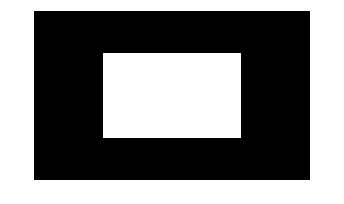

ymin = round(y/4);
xmin = round(x/4);
height = ymin*2;
width = xmin*2;
mask = zeros(x,y);
mask(xmin:(xmin+width),ymin:(ymin+height)) = 1;
imshow(mask,[])

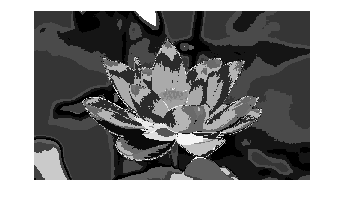

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = double([R(:),G(:),B(:)]);

[L, centroids] = kmeans(O,k);
centroids = round(centroids);
%plot(L(:,1),'.')
[f,c,p] = size(I);
S = reshape(L,[f,c]);
imshow(S,[])

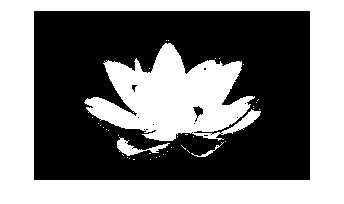

H = [L,mask(:)];
Hist0 = hist(H(H(:,2)==0),[1:k]); %Obtenim els punts de fora 
Hist1 = hist(H(H(:,2)==1),[1:k]); %Obtenim els punts de dins

RES = Hist1 > Hist0;
M = RES(H(:,1)); %Tots els elements de H que tenen una k a 1
MFINAL = reshape(M,size(I,1),size(I,2));
imshow(MFINAL);

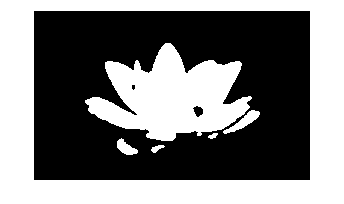


se = strel('disk',5);
MFINAL2 = imopen(MFINAL,se);
MFINAL2 = medfilt2(MFINAL2,[10,10]);
imshow(MFINAL2); 


C = bwconncomp(MFINAL2)

C = struct with fields:
    Connectivity: 8
       ImageSize: [450 735]
      NumObjects: 5
    PixelIdxList: {[65001×1 double]  [1368×1 double]  [430×1 double]  [275×1 double]  [2072×1 double]}
